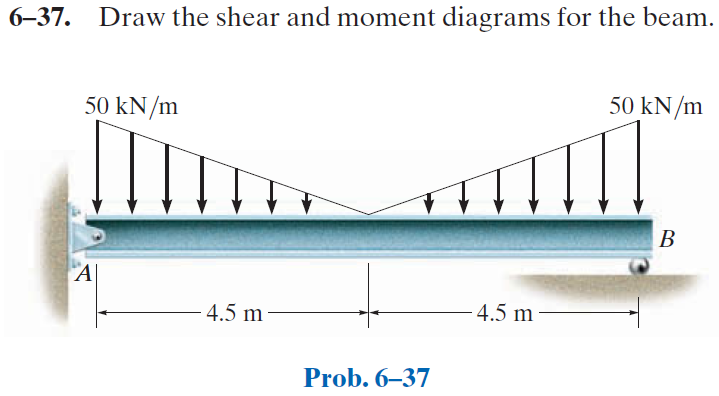

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-37P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-37P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w1 = findpoly(1, 'thru', [0 -50*u.kN/u.m], 'thru', [4.5*u.m 0]);
w2 = findpoly(1, 'thru', [4.5*u.m 0], 'thru', [9*u.m -50*u.kN/u.m]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 9*u.m);
b = b.add('distributed', 'force', w1, [0 4.5]*u.m);
b = b.add('distributed', 'force', w2, [4.5 9]*u.m, [false true]);
b.L = 9*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(-16\,x^{4}+360\,x^{3}\,m-3240\,x^{2}\,m^{2}+98415\,m^{4}\right)}{864\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{5\,\left(x-9\,m\right)\,\left(16\,x^{4}-216\,x^{3}\,m+1296\,x^{2}\,m^{2}-17496\,x\,m^{3}+6561\,m^{4}\right)}{864\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{25\,\left(2\,x-9\,m\right)\,\left(8\,x^{3}-108\,x^{2}\,m+486\,x\,m^{2}+2187\,m^{3}\right)}{864\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{25\,\left(2\,x-9\,m\right)\,\left(8\,x^{3}-108\,x^{2}\,m+486\,x\,m^{2}-3645\,m^{3}\right)}{864\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{25\,x\,\left(4\,x^{2}-54\,x\,m+243\,m^{2}\right)}{54}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{25\,\left(x-9\,m\right)\,\left(4\,x^{2}-18\,x\,m+81\,m^{2}\right)}{54}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{25\,{\left(2\,x-9\,m\right)}^{2}}{18}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{25\,{\left(2\,x-9\,m\right)}^{2}}{18}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} \frac{50\,\left(2\,x-9\,m\right)}{9}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{50\,\left(2\,x-9\,m\right)}{9}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 112.5\,\mathrm{kN}\\ \mathrm{Rb} & 112.5\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and bending moment diagram

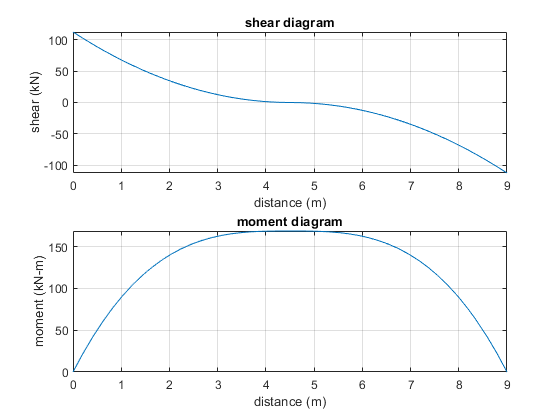

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;